**LEP 6-5 : Algorithm for Liquid Phase Reaction**

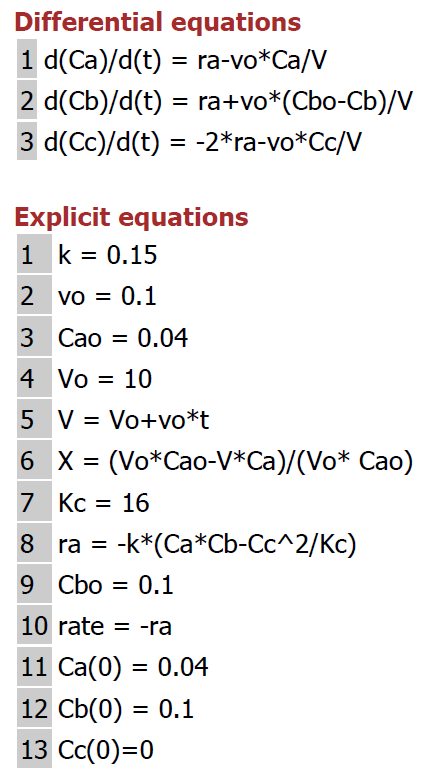

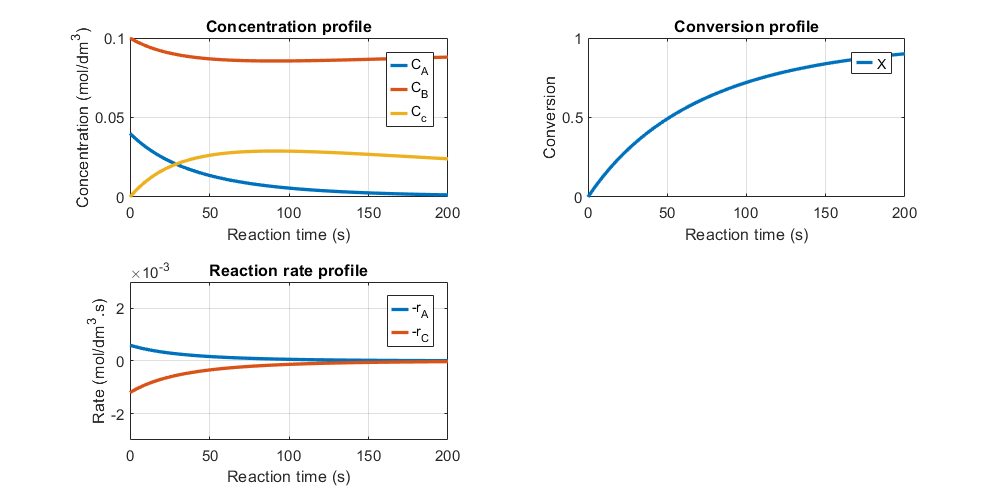

tspan = [0 200]; % Range for the time 
y0 = [0.04 0.1 0 ]; % Initial values for the dependent variables Ca, Cb, Cc
vo = 0.1; 
Vo = 10; 
Kc = 16; 
k = 0.15;
[t,y]=ode45(@(t,y)ODEfun(t,y,vo,Vo,Kc,k),tspan,y0);
tiledlayout(2,2)
set (gcf,'Position',[0,0.1,800,400])
nexttile
plot(t,y(:,1),t,y(:,2),t,y(:,3),'LineWidth',2)
xlabel('Reaction time (s)')
ylabel('Concentration (mol/dm^3)')
leg=legend('C_A','C_B','C_c');
title('Concentration profile')
leg.ItemTokenSize=[10,10];
axis([0 200 0 0.1])
grid on
z=size(y);
Cao=0.04;
for i=1:z(1,1)
V(i) = Vo+vo*t(i); 
X(i)=(Vo*Cao-V(i)*y(i,1))/(Vo* Cao);
ra(i) = -k*(y(i,1)*y(i,2)-y(i,3)^2/Kc); 
rc(i)=-2*ra(i);
end
nexttile
plot(t,X(1:z(1,1)),'LineWidth',2)
xlabel('Reaction time (s)')
ylabel('Conversion')
leg=legend('X');
title('Conversion profile')
leg.ItemTokenSize=[10,10];
axis([0 200 0 1])
grid on
nexttile
plot(t,-ra(1:z(1,1)),t,-rc(1:z(1,1)),'LineWidth',2)
xlabel('Reaction time (s)')
ylabel('Rate (mol/dm^3.s)')
leg=legend('-r_A','-r_C');
title('Reaction rate profile')
leg.ItemTokenSize=[10,10];
axis([0 200 -0.003 0.003])
grid on

function dYfuncvecdt = ODEfun(t,Yfuncvec,vo,Vo,Kc,k); 
Ca = Yfuncvec(1); 
Cb= Yfuncvec(2); 
Cc= Yfuncvec(3);
% Explicit equations
Cbo = 0.1; 
Cao=0.04;
ra = -k*(Ca*Cb-Cc^2/Kc); 
V = Vo+vo*t; 
X=(Vo*Cao-V*Ca)/(Vo* Cao);
% Differential equations
dCadt = ra-vo*Ca/V; 
dCbdt = ra+vo*(Cbo-Cb)/V;
dCcdt = -2*ra-vo*Cc/V; 
dYfuncvecdt =[dCadt; dCbdt;dCcdt];
end